# Junctional Medial Intensity Measurements

## Import necessary files

corePath = '/Volumes/martin/users/cao929/';%Define the shared path for your files on a pc
workingFolder = 'Wilson/';%Define the shared path for your files on a pc     

originalImagePath = strcat(corePath, workingFolder, 'Projections/'); %Define the path to the actin projection
secondImagePath = strcat(corePath, workingFolder, 'Projections2/'); %Define the path to the actin projection
segmentPath = strcat(corePath, workingFolder, 'Segmentation Masks/'); % Define the path to the Segmentation mask
outlinePath = strcat(corePath, workingFolder, 'Outlines/'); %Define the path to the outline
figOutPutDirectory = strcat(corePath, workingFolder, 'Figures/'); %Define the path where figures will be saved

## **Create DataSource**

originalActDS = createDS(originalImagePath, "F-Actin", ".tif");
originalMyoDS = createDS(originalImagePath, "Myosin", ".tif");

secondActDS = createDS(secondImagePath, "F-Actin", ".tif");
secondMyoDS = createDS(secondImagePath, "Myosin", ".tif");

maskDS = fileDatastore(segmentPath, "ReadFcn", @maskRead, "FileExtensions", ".png");
maskDS.Files = maskDS.Files(~contains(maskDS.Files, "._"));

outlineDS = fileDatastore(outlinePath, "ReadFcn", @importdata, "FileExtensions", ".txt");
outlineDS.Files = outlineDS.Files(~contains(outlineDS.Files, "._"));

pairDS = combine(originalActDS, originalMyoDS, secondActDS, secondMyoDS, maskDS, outlineDS);
dsReadCount = 1;

## **Measurements**

while hasdata(pairDS)
    dsSource = read(pairDS);
    originalAct = dsSource{1};
    originalMyo = dsSource{2};
    projectAct = dsSource{3};
    projectMyo = dsSource{4};
    segmentation = dsSource{5};
    fileName = pairDS.UnderlyingDatastores{1, 1}.Files{dsReadCount, 1};
    splitFile = strsplit(fileName, filesep);
    imName = strtok(splitFile{end}, "_");
    outlines = dsSource{6};

## Prepare outlines for junctional vs medial comparison

    rowOutline = reshape(outlines',2, []); %convert the outline matrix into a 2 row matrix so that coordinates listed as y,x
    rowOutline = rowOutline'; %switch row matrix to be two columns
    noNan = rowOutline(~isnan(rowOutline))+1; %Pull out all values that are not NaN, adjust index from 0 to 1
    noNan = reshape(noNan, [], 2); %reshape from single column back to two columns
    
    junctions = ones(size(originalAct)); %create a 2048x2048 matrix of just ones as a base image
    for i = 1:length(noNan)
        junctions(noNan(i,2),noNan(i,1)) = 0; %for each coordinate pair, reassign the one to be zero to "remove" areas of junction from the image"
    end
    
    disc = strel('disk',5); %creates a disk structural element of radius five
    thickJxns = imerode(junctions, disc); %use the disk to increase the thickness of the junctions


### Optional: Show the images and the segmenations

    % figure
    % imshow(originalMyo)
    % figure
    % justJxn = double(originalMyo).*~thickJxns;
    % imshow(uint8(justJxn))
    % figure
    % justMed = double(originalMyo).*thickJxns;
    % imshow(uint8(justMed))
    % 
    % figure
    % imshow(projectMyo)
    % figure
    % justJxn = double(projectMyo).*~thickJxns;
    % imshow(uint8(justJxn))
    % figure
    % justMed = double(projectMyo).*thickJxns;
    % imshow(uint8(justMed))

## Pull out Whole Cell Intensity Data using the segmentation

    measMyo = regionprops(segmentation, originalMyo, "Area", "Centroid", ...
        "PixelValues", "Orientation", "MajorAxisLength", "MinorAxisLength"); %Pull out area, center, and all pixel intensities for each region
    measAct = regionprops(segmentation, originalAct, "PixelValues"); %Pull out pixel intensities. Only need area and center from one image because they are shared
    
    measMyo2 = regionprops(segmentation, projectMyo, "Area", "Centroid", ...
        "PixelValues", "Orientation", "MajorAxisLength", "MinorAxisLength");
    measAct2 = regionprops(segmentation, projectAct, "PixelValues");
    
    centers = [measMyo.Centroid]; %Pull out the coordinates for the centers of each cell
    yPos = centers(2:2:end)'; %Create a vector of y-positions
    xPos = centers(1:2:end)'; %Create a vector of x-positions
    
    resolution = 2.4089*2.4089; %Define the pixels^2/µm^2 resolution
    area = [measMyo.Area]'/resolution; %convert pixel areas to µm
    avgArea = mean(area); %Calculate the average area
    normArea = (area - avgArea)/avgArea; %Calculate the normalized area
    
    [totIntMyo, avgIntMyo, normMyo, normAvgMyo] = normalize(measMyo);
    
    [totIntAct, avgIntAct, normAct, normAvgAct] = normalize(measAct);
    
    [totIntMyo2, avgIntMyo2, normMyo2, normAvgMyo2] = normalize(measMyo2);
    
    [totIntAct2, avgIntAct2, normAct2, normAvgAct2] = normalize(measAct2);
    
    % Calculate the difference in intensity between layers as a ratio
    [diffTotalMyo, diffTotalAct, diffAvgMyo, diffAvgAct, ratioTotalMyo, ratioTotalAct, ratioAvgMyo, ratioAvgAct] = calculateDiff(totIntMyo, totIntMyo2, totIntAct, totIntAct2, avgIntMyo, avgIntMyo2, avgIntAct, avgIntAct2);

## Calculate medial and junctional intensities

    medSegmentation = segmentation.*thickJxns; %remove the junctional section from all of the cells
    medMyo = regionprops(medSegmentation, originalMyo, "Area", "PixelValues"); %Pull pixel intensities for medial pool of myosin
    medAct = regionprops(medSegmentation, originalAct, "PixelValues"); %Pull pixel intensitiesfor medial pool of actin
    medMyo2 = regionprops(medSegmentation, projectMyo, "PixelValues");
    medAct2 = regionprops(medSegmentation, projectAct, "PixelValues");
    
    jxnSegmentation = segmentation.*~thickJxns; %remove the medial region of all the cells
    jxnMyo = regionprops(jxnSegmentation, originalMyo, "Area", "PixelValues"); %Pull pixel intensities for junctional pool of myosin
    jxnAct = regionprops(jxnSegmentation, originalAct, "PixelValues"); %Pull pixel intensitiesfor junctional pool of actin
    jxnMyo2 = regionprops(jxnSegmentation, projectMyo, "PixelValues");
    jxnAct2 = regionprops(jxnSegmentation, projectAct, "PixelValues");
    
    %Calculate the areas of the medial and junctional pools in µm
    medArea = [medMyo.Area]'/resolution; 
    avgMedArea = mean(medArea);
    jxnArea = [jxnMyo.Area]'/resolution;
    avgJxnArea = mean(jxnArea);
    
    [totMedMyo, avgMedMyo, totJxnMyo, avgJxnMyo, normMedMyo, normJxnMyo, normAvgMedMyo, normAvgJxnMyo] = junctionCalculate(medMyo, jxnMyo, measMyo);
    
    [totMedAct, avgMedAct, totJxnAct, avgJxnAct, normMedAct, normJxnAct, normAvgMedAct, normAvgJxnAct] = junctionCalculate(medAct, jxnAct, measAct);
    
    [totMedMyo2, avgMedMyo2, totJxnMyo2, avgJxnMyo2, normMedMyo2, normJxnMyo2, normAvgMedMyo2, normAvgJxnMyo2] = junctionCalculate(medMyo2, jxnMyo2, measMyo2);
    
    [totMedAct2, avgMedAct2, totJxnAct2, avgJxnAct2, normMedAct2, normJxnAct2, normAvgMedAct2, normAvgJxnAct2] = junctionCalculate(medAct2, jxnAct2, measAct2);
    
    [diffTotalJxnMyo, diffTotalJxnAct, diffAvgJxnMyo, diffAvgJxnAct, ratioTotalJxnMyo, ratioTotalJxnAct, ratioAvgJxnMyo, ratioAvgJxnAct] = calculateDiff(totJxnMyo, totJxnMyo2, totJxnAct, totJxnAct2, avgJxnMyo, avgJxnMyo2, avgJxnAct, avgJxnAct2);
    [diffTotalMedMyo, diffTotalMedAct, diffAvgMedMyo, diffAvgMedAct, ratioTotalMedMyo, ratioTotalMedAct, ratioAvgMedMyo, ratioAvgMedAct] = calculateDiff(totMedMyo, totMedMyo2, totMedAct, totMedAct2, avgMedMyo, avgMedMyo2, avgMedAct, avgMedAct2);


## Create data table and sort 

    %Create a table of all the calculate values to allow for pairing and sorting of data
    measTable = table(area, normArea, yPos, xPos, totIntAct, avgIntAct, normAct, normAvgAct, ...
        totMedAct, avgMedAct, normMedAct, normAvgMedAct, ...
        totJxnAct, avgJxnAct, normJxnAct, normAvgJxnAct, ...
        totIntMyo, avgIntMyo, normMyo, normAvgMyo, ...
        totMedMyo, avgMedMyo, normMedMyo, normAvgMedMyo, ...
        totJxnMyo, avgJxnMyo, normJxnMyo, normAvgJxnMyo, ...
        diffTotalMyo, diffTotalAct, diffAvgMyo, diffAvgAct, ...
        ratioTotalMyo, ratioTotalAct, ratioAvgMyo, ratioAvgAct, ...
        diffTotalJxnMyo, diffTotalJxnAct, diffAvgJxnMyo, diffAvgJxnAct, ...
        ratioTotalJxnMyo, ratioTotalJxnAct, ratioAvgJxnMyo, ratioAvgJxnAct, ...
        diffTotalMedMyo, diffTotalMedAct, diffAvgMedMyo, diffAvgMedAct, ...
        ratioTotalMedMyo, ratioTotalMedAct, ratioAvgMedMyo, ratioAvgMedAct);

## Define diverging color maps

    %Define the RGB codes for several color maps that will be used below
    divPWG = [0,68,27; 27,120,55; 90,174,97; 166,219,160; 217,240,211; 247,247,247; 231,212,232; 194,165,207; 153,112,171; 118,42,131; 64,0,75;]/255;
    divRWB =[103,0,31; 178,24,43; 214,96,77; 244,165,130; 253,219,199; 247,247,247; 209,229,240; 146,197,222; 67,147,195; 33,102,172; 5,48,97;]/255;
    divPiWG = [ 39,100,25; 77,146,33; 127,188,65; 184,225,134; 230,245,208; 247,247,247; 253,224,239; 241,182,218; 222,119,174; 197,27,125; 142,1,82;]/255;

## Plot Normalized Area

    whole = true;
    jxn = true;
    med = true;
    diff = true;
    ratio = true;
    
    if whole == true
        if diff == true
            figure
            segVis(segmentation, junctions, measTable.diffTotalAct, divRWB, 'k', 16, [-1, 1], "Percentage Change") %request to make an plot visualizing the segmentation
            newOutPutDirectory = strcat(figOutPutDirectory, '_diffTotalAct.png'); %Give your plot a descriptive name
            exportgraphics(gcf, newOutPutDirectory,'Resolution', 600);
            
            figure
            segVis(segmentation, junctions, measTable.diffAvgAct, divRWB, 'k', 16, [-1, 1], "Percentage Change") %request to make an plot visualizing the segmentation
            newOutPutDirectory = strcat(figOutPutDirectory, '_diffAvgAct.png'); %Give your plot a descriptive name
            exportgraphics(gcf, newOutPutDirectory,'Resolution', 600);
            
            figure
            segVis(segmentation, junctions, measTable.diffTotalMyo, divRWB, 'k', 16, [-1, 1], "Percentage Change") %request to make an plot visualizing the segmentation
            newOutPutDirectory = strcat(figOutPutDirectory, '_diffTotalMyo.png'); %Give your plot a descriptive name
            exportgraphics(gcf, newOutPutDirectory,'Resolution', 600);
            
            figure
            segVis(segmentation, junctions, measTable.diffAvgMyo, divRWB, 'k', 16, [-1, 1], "Percentage Change") %request to make an plot visualizing the segmentation
            newOutPutDirectory = strcat(figOutPutDirectory, '_diffAvgMyo.png'); %Give your plot a descriptive name
            exportgraphics(gcf, newOutPutDirectory,'Resolution', 600);
        end
        if ratio == true
            figure
            segVis(segmentation, junctions, measTable.ratioTotalAct, divRWB, 'k', 16, [0, 2], "Ratio") %request to make an plot visualizing the segmentation
            newOutPutDirectory = strcat(figOutPutDirectory, '_ratioTotalAct.png'); %Give your plot a descriptive name
            exportgraphics(gcf, newOutPutDirectory,'Resolution', 600);
            
            figure
            segVis(segmentation, junctions, measTable.ratioAvgAct, divRWB, 'k', 16, [0, 2], "Ratio") %request to make an plot visualizing the segmentation
            newOutPutDirectory = strcat(figOutPutDirectory, '_ratioAvgAct.png'); %Give your plot a descriptive name
            exportgraphics(gcf, newOutPutDirectory,'Resolution', 600);
            
            figure
            segVis(segmentation, junctions, measTable.ratioTotalMyo, divRWB, 'k', 16, [0, 2], "Ratio") %request to make an plot visualizing the segmentation
            newOutPutDirectory = strcat(figOutPutDirectory, '_ratioTotalMyo.png'); %Give your plot a descriptive name
            exportgraphics(gcf, newOutPutDirectory,'Resolution', 600);
            
            figure
            segVis(segmentation, junctions, measTable.ratioAvgMyo, divRWB, 'k', 16, [0, 2], "Ratio") %request to make an plot visualizing the segmentation
            newOutPutDirectory = strcat(figOutPutDirectory, '_ratioAvgMyo.png'); %Give your plot a descriptive name
            exportgraphics(gcf, newOutPutDirectory,'Resolution', 600);
        end
    end
    
    if jxn == true
        if diff == true
            figure
            segVis(segmentation, junctions, measTable.diffTotalJxnMyo, divRWB, 'k', 16, [-1, 1], "Percentage Change") %request to make an plot visualizing the segmentation
            newOutPutDirectory = strcat(figOutPutDirectory, '_diffTotalJxnMyo.png'); %Give your plot a descriptive name
            exportgraphics(gcf, newOutPutDirectory,'Resolution', 600);
            
            figure
            segVis(segmentation, junctions, measTable.diffTotalJxnAct, divRWB, 'k', 16, [-1, 1], "Percentage Change") %request to make an plot visualizing the segmentation
            newOutPutDirectory = strcat(figOutPutDirectory, '_diffTotalJxnAct.png'); %Give your plot a descriptive name
            exportgraphics(gcf, newOutPutDirectory,'Resolution', 600);
            
            figure
            segVis(segmentation, junctions, measTable.diffAvgJxnMyo, divRWB, 'k', 16, [-1, 1], "Percentage Change") %request to make an plot visualizing the segmentation
            newOutPutDirectory = strcat(figOutPutDirectory, '_diffAvgJxnMyo.png'); %Give your plot a descriptive name
            exportgraphics(gcf, newOutPutDirectory,'Resolution', 600);
            
            figure
            segVis(segmentation, junctions, measTable.diffAvgJxnAct, divRWB, 'k', 16, [-1, 1], "Percentage Change") %request to make an plot visualizing the segmentation
            newOutPutDirectory = strcat(figOutPutDirectory, '_diffAvgJxnAct.png'); %Give your plot a descriptive name
            exportgraphics(gcf, newOutPutDirectory,'Resolution', 600);
        end
        if ratio == true
            figure
            segVis(segmentation, junctions, measTable.ratioTotalJxnAct, divRWB, 'k', 16, [0, 2], "Ratio") %request to make an plot visualizing the segmentation
            newOutPutDirectory = strcat(figOutPutDirectory, '_ratioTotalJxnAct.png'); %Give your plot a descriptive name
            exportgraphics(gcf, newOutPutDirectory,'Resolution', 600);
            
            figure
            segVis(segmentation, junctions, measTable.ratioAvgJxnAct, divRWB, 'k', 16, [0, 2], "Ratio") %request to make an plot visualizing the segmentation
            newOutPutDirectory = strcat(figOutPutDirectory, '_ratioAvgJxnAct.png'); %Give your plot a descriptive name
            exportgraphics(gcf, newOutPutDirectory,'Resolution', 600);
            
            figure
            segVis(segmentation, junctions, measTable.ratioTotalJxnMyo, divRWB, 'k', 16, [0, 2], "Ratio") %request to make an plot visualizing the segmentation
            newOutPutDirectory = strcat(figOutPutDirectory, '_ratioTotalJxnMyo.png'); %Give your plot a descriptive name
            exportgraphics(gcf, newOutPutDirectory,'Resolution', 600);
            
            figure
            segVis(segmentation, junctions, measTable.ratioAvgJxnMyo, divRWB, 'k', 16, [0, 2], "Ratio") %request to make an plot visualizing the segmentation
            newOutPutDirectory = strcat(figOutPutDirectory, '_ratioAvgJxnMyo.png'); %Give your plot a descriptive name
            exportgraphics(gcf, newOutPutDirectory,'Resolution', 600);
        end
    end
    
    if med == true
        if diff == true
            figure
            segVis(segmentation, junctions, measTable.diffTotalMedMyo, divRWB, 'k', 16, [-1, 1], "Percentage Change") %request to make an plot visualizing the segmentation
            newOutPutDirectory = strcat(figOutPutDirectory, '_diffTotalMedMyo.png'); %Give your plot a descriptive name
            exportgraphics(gcf, newOutPutDirectory,'Resolution', 600);
            
            figure
            segVis(segmentation, junctions, measTable.diffTotalMedAct, divRWB, 'k', 16, [-1, 1], "Percentage Change") %request to make an plot visualizing the segmentation
            newOutPutDirectory = strcat(figOutPutDirectory, '_diffTotalMedAct.png'); %Give your plot a descriptive name
            exportgraphics(gcf, newOutPutDirectory,'Resolution', 600);
            
            figure
            segVis(segmentation, junctions, measTable.diffAvgMedMyo, divRWB, 'k', 16, [-1, 1], "Percentage Change") %request to make an plot visualizing the segmentation
            newOutPutDirectory = strcat(figOutPutDirectory, '_diffAvgMedMyo.png'); %Give your plot a descriptive name
            exportgraphics(gcf, newOutPutDirectory,'Resolution', 600);
            
            figure
            segVis(segmentation, junctions, measTable.diffAvgMedAct, divRWB, 'k', 16, [-1, 1], "Percentage Change") %request to make an plot visualizing the segmentation
            newOutPutDirectory = strcat(figOutPutDirectory, '_diffAvgMedAct.png'); %Give your plot a descriptive name
            exportgraphics(gcf, newOutPutDirectory,'Resolution', 600);
        end
        if ratio == true
            figure
            segVis(segmentation, junctions, measTable.ratioTotalMedAct, divRWB, 'k', 16, [0, 2], "Ratio") %request to make an plot visualizing the segmentation
            newOutPutDirectory = strcat(figOutPutDirectory, '_ratioTotalMedAct.png'); %Give your plot a descriptive name
            exportgraphics(gcf, newOutPutDirectory,'Resolution', 600);
            
            figure
            segVis(segmentation, junctions, measTable.ratioAvgMedAct, divRWB, 'k', 16, [0, 2], "Ratio") %request to make an plot visualizing the segmentation
            newOutPutDirectory = strcat(figOutPutDirectory, '_ratioAvgMedAct.png'); %Give your plot a descriptive name
            exportgraphics(gcf, newOutPutDirectory,'Resolution', 600);
            
            figure
            segVis(segmentation, junctions, measTable.ratioTotalMedMyo, divRWB, 'k', 16, [0, 2], "Ratio") %request to make an plot visualizing the segmentation
            newOutPutDirectory = strcat(figOutPutDirectory, '_ratioTotalMedMyo.png'); %Give your plot a descriptive name
            exportgraphics(gcf, newOutPutDirectory,'Resolution', 600);
            
            figure
            segVis(segmentation, junctions, measTable.ratioAvgMedMyo, divRWB, 'k', 16, [0, 2], "Ratio") %request to make an plot visualizing the segmentation
            newOutPutDirectory = strcat(figOutPutDirectory, '_ratioAvgMedMyo.png'); %Give your plot a descriptive name
            exportgraphics(gcf, newOutPutDirectory,'Resolution', 600);
        end
    end
end

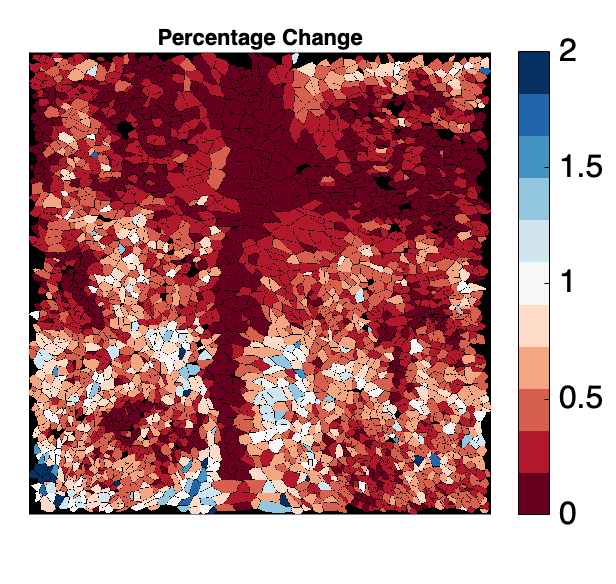

    figure
%     test = (measTable.ratioAvgMedAct)
    segVis(segmentation, junctions, measTable.diffAvgJxnAct, divRWB, 'k', 16, [0, 2], "Percentage Change") %request to make an plot visualizing the segmentation
    newOutPutDirectory = strcat(figOutPutDirectory, imName,'_Test2.png'); %Give your plot a descriptive name
    exportgraphics(gcf, newOutPutDirectory,'Resolution', 600);

function [totInt, avgInt, norm, normAvg] = normalize(meas)
%Create two empty vectors of the same length as the number of cells in the image
totInt = zeros(length(meas),1); 
avgInt = zeros(length(meas),1);

%For each cell calculate the total (sum) intenstity and average intensity of myosin and save into the relevant vecors
for i = 1:length(meas) 
    totInt(i) = sum(meas(i).PixelValues);
    avgInt(i) = mean(meas(i).PixelValues);
    
end
avgCell = mean(totInt); %Find the average total intensity across all cells
avgAvg = mean(avgInt); %Find the average avereae intensity across all cells
norm = (totInt - avgCell)/avgCell; %Calculate the normalized total intensity
normAvg = (avgInt - avgAvg)/avgAvg; %Calculate the normalized average total intensity
end

function [totMed, avgMed, totJxn, avgJxn, normMed, normJxn, normAvgMed, normAvgJxn] = junctionCalculate(med, jxn, meas)
%Measure the total and average intensities for both the junctional and medial myosin pools
totMed = zeros(length(med),1);
avgMed = zeros(length(med),1);
totJxn = zeros(length(jxn),1);
avgJxn = zeros(length(jxn),1);
for i = 1:length(meas)
    totMed(i) = sum(med(i).PixelValues);
    avgMed(i) = mean(med(i).PixelValues);
    totJxn(i) = sum(jxn(i).PixelValues);
    avgJxn(i) = mean(jxn(i).PixelValues);
end
%Calculate the average for both the total/average intensities in junctional and medial pools of myosin
avgTotMedMyo = mean(totMed);
avgTotJxnMyo = mean(totJxn);
avgAvgMedMyo = mean(avgMed(~isnan(avgMed)));
avgAvgJxnMyo = mean(avgJxn(~isnan(avgJxn)));
%Normalize the above measurements for Myosin
normMed = (totMed - avgTotMedMyo)/avgTotMedMyo;
normJxn = (totJxn - avgTotJxnMyo)/avgTotJxnMyo;
normAvgMed = (avgMed - avgAvgMedMyo)/avgAvgMedMyo;
normAvgJxn = (avgJxn - avgAvgJxnMyo)/avgAvgJxnMyo;
end

function percentChange = percentage_Change(totInt, totInt2)
percentChange = (totInt - totInt2) ./ totInt2;
end

function ratio = find_ratio(totInt, totInt2)
ratio = totInt ./ totInt2;
end

function [diffTotalMyo, diffTotalAct, diffAvgMyo, diffAvgAct, ratioTotalMyo, ratioTotalAct, ratioAvgMyo, ratioAvgAct] = calculateDiff(totIntMyo, totIntMyo2, totIntAct, totIntAct2, avgIntMyo, avgIntMyo2, avgIntAct, avgIntAct2)
diffTotalMyo = percentage_Change(totIntMyo, totIntMyo2);
diffTotalAct = percentage_Change(totIntAct, totIntAct2);
diffAvgMyo = percentage_Change(avgIntMyo, avgIntMyo2);
diffAvgAct = percentage_Change(avgIntAct, avgIntAct2);

ratioTotalMyo = find_ratio(totIntMyo, totIntMyo2);
ratioTotalAct = find_ratio(totIntAct, totIntAct2);
ratioAvgMyo = find_ratio(avgIntMyo, avgIntMyo2);
ratioAvgAct = find_ratio(avgIntAct, avgIntAct2);
end

function [ds] = createDS(ImagePath, contain, type)
ds = fileDatastore(ImagePath, "ReadFcn", @imread, "FileExtensions", type);
ds.Files = ds.Files(contains(ds.Files, contain));
ds.Files = ds.Files(~contains(ds.Files, "._"));
end

function [mask] = maskRead(image)
mask = double(imread(image));
end